clear;

data =  readtable('C:\Users\rgs88\OneDrive\Documents\Semester 1 Data Science MSc Projects\Machine Learning\ML_Project\wine_quality_df_cleaned.csv');

data;

X = data(:, [1:13]);
Y = data(:, 14);

[numSamples, ~] = size(X)

numSamples = 2477

splitRatio = 0.7;

numTrainSamples = floor(numSamples * splitRatio);

indices = randperm(numSamples);

x_train = X(indices(1:numTrainSamples), :);
y_train = Y(indices(1:numTrainSamples), :);
x_test = X(indices(numTrainSamples+1:end), :);
y_test = Y(indices(numTrainSamples+1:end), :);

X_train = table2array(x_train);
Y_train = table2array(y_train);
X_test = table2array(x_test);
Y_test = table2array(y_test);

knn_mdl = fitcknn(X_train, Y_train, 'NumNeighbors', 3);

Y_pred_labels = predict(knn_mdl, X_test);

% Evaluate the model
accuracy = sum(Y_pred_labels == Y_test) / numel(Y_test);

% Display accuracy
disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 79.3011%


% Create a confusion matrix
C = confusionmat(Y_test, Y_pred_labels);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    97     1     0     1     0     0
     0   127     5     4     0     0
     0     7    78    41     6     0
     1    11    36    67     3     0
     0     0     9    24    95     1
     0     0     3     1     0   126



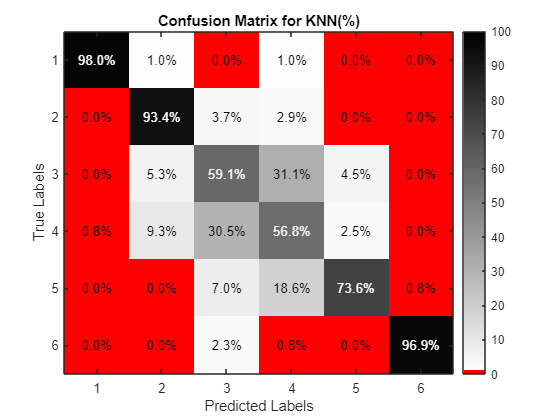

% Convert the confusion matrix to a percentage format
C_percent = 100 * C ./ sum(C, 2);

% Define custom colormap with red background and white text
redBackground = [1, 0, 0];
blackText = [0, 0, 0];
whiteText = [1, 1, 1];

% Create a custom colormap with red background and shades of white for text
customColormap = [redBackground; interp1([0, 100], [whiteText; blackText], 1:100)];

% Visualize the confusion matrix as a heatmap using imagesc
figure;
h = imagesc(C_percent);
colorbar;
colormap(customColormap);
clim([0, 100]); % Set the color axis range to match the percentages
title('Confusion Matrix for KNN(%)');
xlabel('Predicted Labels');
ylabel('True Labels');

% Display the percentage values on the heatmap in white or black based on intensity
textColors = repmat(C_percent(:) > 50, 1, 3); % Define text colors based on background intensity
textStrings = strtrim(cellstr(num2str(C_percent(:), '%.1f%%'))); % Convert values to string
[x, y] = meshgrid(1:size(C_percent, 2), 1:size(C_percent, 1)); % Create coordinate grid
text(x(:), y(:), textStrings(:), 'HorizontalAlignment', 'center', 'Color', 'k');

% Display the diagonal values in white text on the heatmap
for i = 1:size(C_percent, 1)
    text(i, i, num2str(C_percent(i, i), '%.1f%%'), 'HorizontalAlignment', 'center', 'Color', 'w');
end

% Calculate the observed agreement
po = sum(diag(C)) / sum(C(:));

% Calculate the chance agreement
pe = sum(sum(C, 1) .* sum(C, 2)) / sum(C(:))^2;

% Calculate Cohen's Kappa
kappa = (po - pe) / (1 - pe);

disp(['Cohen''s Kappa: ' num2str(kappa)]);

Cohen's Kappa: 0.75181


% Define the range of hyperparameters to search
numNeighbors = [1, 3, 5, 7, 9]; % Example values for the number of neighbors

% Initialize variables to store best results
bestAccuracy = 0;
bestNumNeighbors = 0;
bestModel = [];

% Initialize array to store accuracies
allAccuracies = zeros(1, length(numNeighbors));

% Perform Grid Search
for i = 1:length(numNeighbors)
    k = numNeighbors(i);
    knn_mdl = fitcknn(X_train, Y_train, 'NumNeighbors', k);
    y_pred_labels = predict(knn_mdl, X_test);
    accuracy = sum(Y_pred_labels == Y_test) / length(Y_test);
    
    disp(['NumNeighbors: ' num2str(k) ', Accuracy: ' num2str(accuracy)]);
    
    % Update best model if accuracy is better
    if accuracy > bestAccuracy
        bestAccuracy = accuracy;
        bestNumNeighbors = k;
        bestModel = knn_mdl;
    end
    
    % Store accuracy in the array
    allAccuracies(i) = accuracy;
end

NumNeighbors: 1, Accuracy: 0.79301
NumNeighbors: 3, Accuracy: 0.79301
NumNeighbors: 5, Accuracy: 0.79301
NumNeighbors: 7, Accuracy: 0.79301
NumNeighbors: 9, Accuracy: 0.79301



% Display all accuracies
disp('All Accuracies:');

All Accuracies:


disp(allAccuracies);

    0.7930    0.7930    0.7930    0.7930    0.7930




disp(['Best NumNeighbors: ' num2str(bestNumNeighbors)]);

Best NumNeighbors: 1


disp(['Best Accuracy: ' num2str(bestAccuracy)]);

Best Accuracy: 0.79301


% Create a confusion matrix
C = confusionmat(Y_test, Y_pred_labels);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    97     1     0     1     0     0
     0   127     5     4     0     0
     0     7    78    41     6     0
     1    11    36    67     3     0
     0     0     9    24    95     1
     0     0     3     1     0   126



numClasses = size(C, 1);
precision = zeros(1, numClasses);
recall = zeros(1, numClasses);
f1_score = zeros(1, numClasses);

for i = 1:numClasses
    TP = C(i, i);
    FP = sum(C(:, i)) - TP;
    FN = sum(C(i, :)) - TP;
    
    precision(i) = TP / (TP + FP);
    recall(i) = TP / (TP + FN);
    f1_score(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));
end

avgPrecision = mean(precision);
avgRecall = mean(recall);
avgF1Score = mean(f1_score);

% Display results
disp(['Average Precision: ', num2str(avgPrecision)]);

Average Precision: 0.8077


disp(['Average Recall: ', num2str(avgRecall)]);

Average Recall: 0.79633


disp(['Average F1 Score: ', num2str(avgF1Score)]);

Average F1 Score: 0.79968


final_model_knn = fitcknn(X_train, Y_train, 'NumNeighbors', 1);

y_pred_labels = predict(final_model_knn, X_test);

% Create a confusion matrix
C2 = confusionmat(Y_test, y_pred_labels);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(C2);

    97     0     0     1     1     0
     0   128     6     2     0     0
     0     7    68    45    12     0
     1     4    47    56     9     1
     0     0    11    16   101     1
     0     0     3     1     0   126



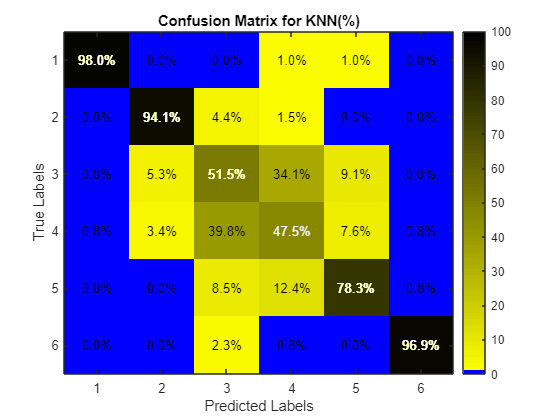

CM_percent = 100 * C2 ./ sum(C2, 2);

% Define custom colors
blueBackground = [0, 0, 1]; % Blue background
yellowText = [1, 1, 0]; % Yellow text
blackText = [0, 0, 0]; % Black text

% Create a custom colormap with blue background and shades of yellow for text
customColormap = [blueBackground; interp1([0, 100], [yellowText; blackText], 1:100)];

% Visualize the confusion matrix as a heatmap using imagesc
figure;
h = imagesc(CM_percent);
colorbar;
colormap(customColormap);
clim([0, 100]); % Set the color axis range to match the percentages
title('Confusion Matrix for KNN(%)');
xlabel('Predicted Labels');
ylabel('True Labels');

% Display the percentage values on the heatmap
textColors = repmat(CM_percent(:) > 50, 1, 3); % Define text colors based on background intensity
textStrings = strtrim(cellstr(num2str(CM_percent(:), '%.1f%%'))); % Convert values to string
[x, y] = meshgrid(1:size(CM_percent, 2), 1:size(CM_percent, 1)); % Create coordinate grid
for i = 1:length(textStrings)
    textColor = blackText; % Default text color
    if CM_percent(i) > 50
        textColor = yellowText; % Change text color for better contrast
    end
    text(x(i), y(i), textStrings{i}, 'HorizontalAlignment', 'center', 'Color', textColor);
end

% Ensure diagonal values stand out
for i = 1:size(CM_percent, 1)
    text(i, i, num2str(CM_percent(i, i), '%.1f%%'), 'HorizontalAlignment', 'center', 'Color', 'w');
end